# **Non-blind Deblurring**

#### Read Images

clear;
lena = imread('lena.png');
motion_blur_kernel = im2double(imread('mb-kernel.png'));
motion_blur_kernel = motion_blur_kernel/(sum(motion_blur_kernel(:)));

#### Define Parameters as given

qx = [1 -1];
qy = transpose(qx);
l_start = 0.01;
l_end = 2.0;
l_step = 0.01;
n_lambdas = length(l_start:l_step:l_end);

## Perform NBD using L2 norm based gradient regularization

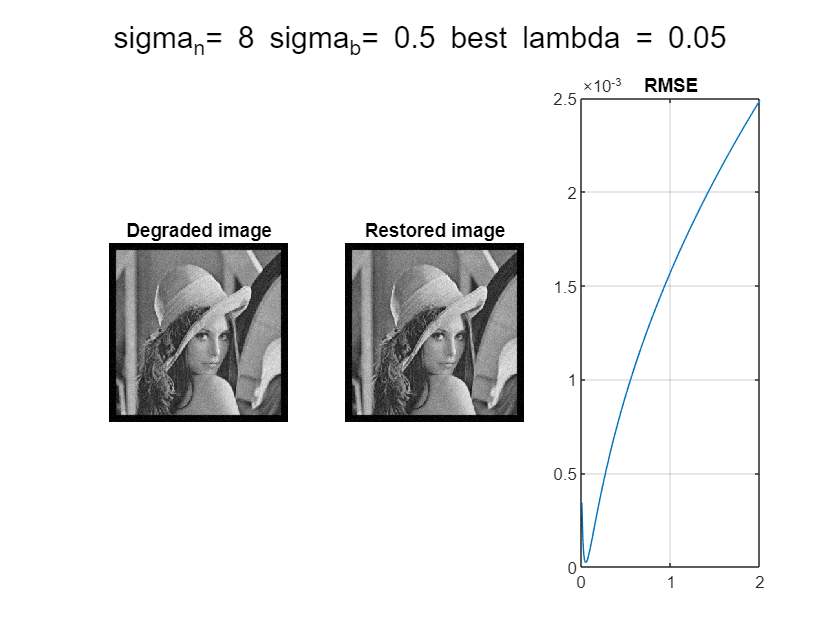

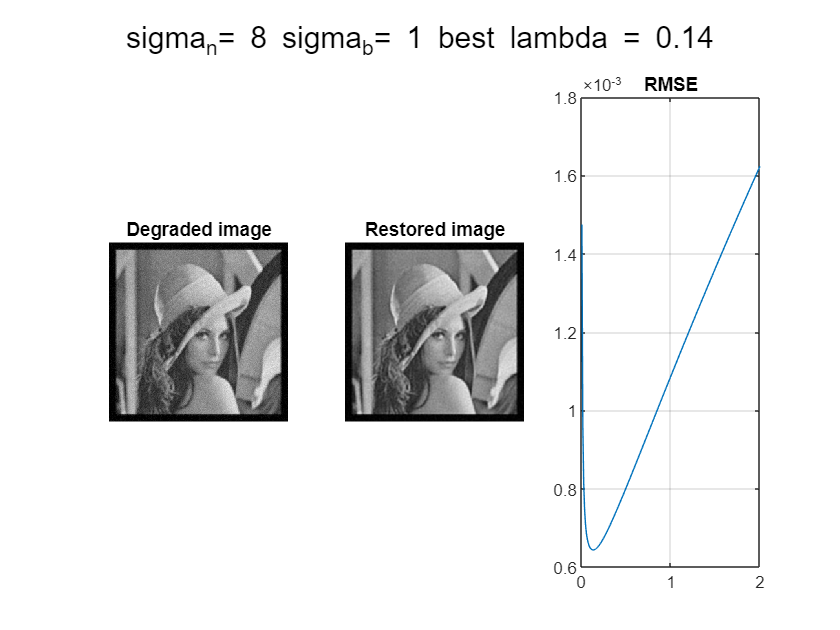

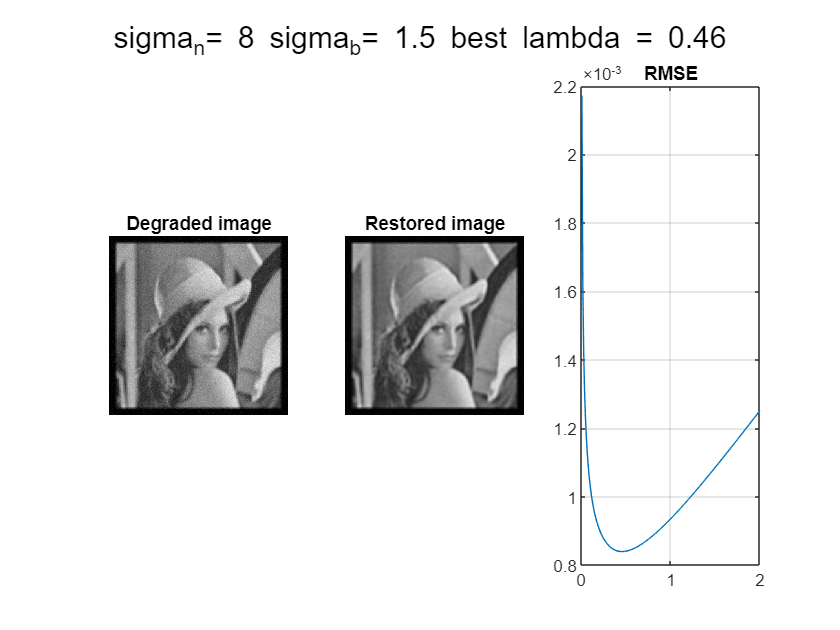

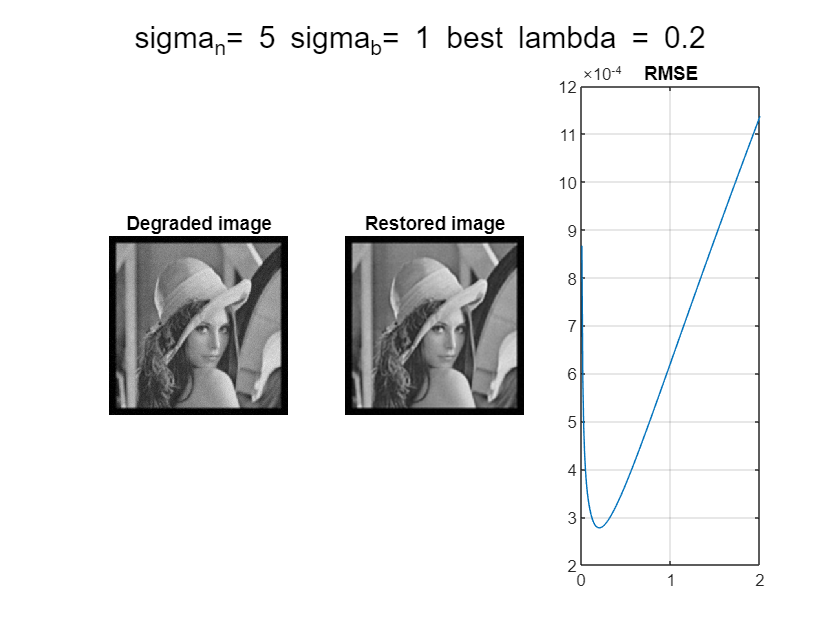

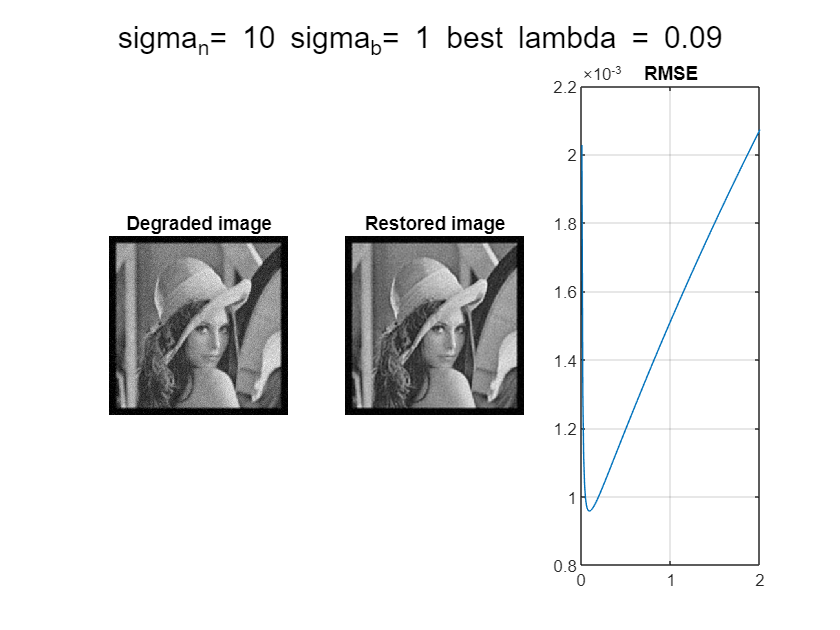

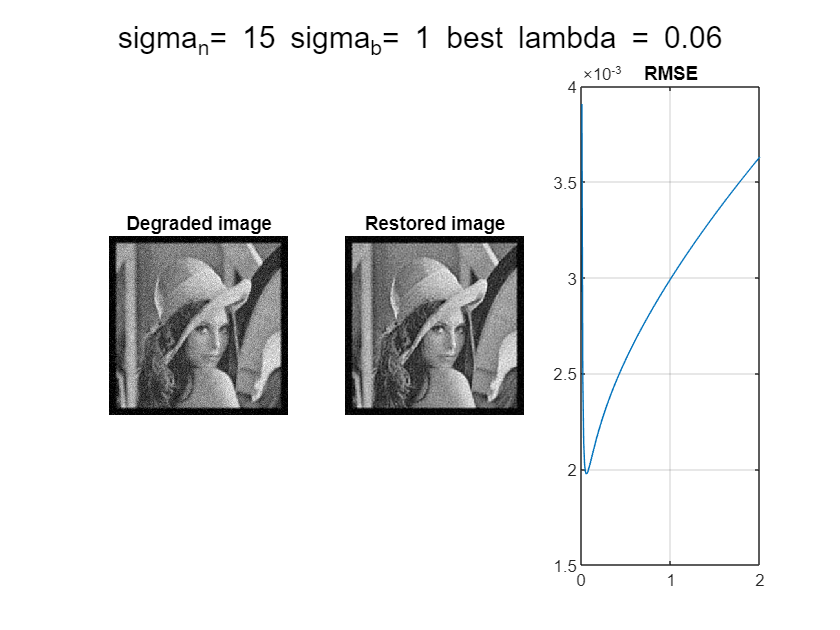

sigma_n_vals = [8 8 8 5 10 15];
sigma_b_vals = [0.5 1 1.5 1 1 1];
best_lambdas = zeros(size(sigma_b_vals));
rmse_vals = zeros(length(sigma_n_vals), n_lambdas);

for i = 1:length(sigma_n_vals)
    sigma_n = sigma_n_vals(i);
    sigma_b = sigma_b_vals(i);
    [best_l, RMSE] = best_lambda(lena, qx, qy, sigma_b, sigma_n, ...
        l_start, l_end, l_step, false, "L2");
    best_lambdas(i) = best_l;
    rmse_vals(i, :) = RMSE;
    degraded_image = degrade(lena, sigma_b, sigma_n, false);
    restored_image = deblur_L2_freq(degraded_image, sigma_b, best_l, ...
        qx, qy, false);
        
    figure;
    subplot(1,3,1);
    imshow(degraded_image)
    title('Degraded image')
    subplot(1,3,2);
    imshow(restored_image)
    title('Restored image')
    subplot(1,3,3)
    plot(l_start:l_step:l_end, RMSE);
    grid on;
    title('RMSE')
    sgtitle(['sigma_n= ',num2str(sigma_n),' sigma_b= ', ...
        num2str(sigma_b), ' best lambda = ',num2str(best_l)])
end

## L1 vs L2 gradient regularization for NBD

We observe L1 vs L2 based gradient regularization

sigma_n = 1;
sigma_b = 1.5;
degraded_image = degrade(lena, sigma_b, sigma_n, false);
[best_lambda_L1, RMSE_L1] = best_lambda(lena, qx, qy, ...
    sigma_b, sigma_n, l_start, l_end, l_step, false, "L1");
[best_lambda_L2, RMSE_L2] = best_lambda(lena, qx, qy, ...
    sigma_b, sigma_n, l_start, l_end, l_step, false, "L2");
restored_image_L1 = deblur_L1(degraded_image, sigma_b, best_lambda_L1, ...
    false);
restored_image_L2 = deblur_L2_freq(degraded_image, sigma_b, ...
    best_lambda_L2, qx, qy, false);
display(['Best lambda values for sigma_n = ', num2str(sigma_n),' and sigma_b = ', ...
    num2str(sigma_b),' for L1 = ', num2str(best_lambda_L1), ' and for L2 =', ...
    num2str(best_lambda_L2)])

Best lambda values for sigma_n = 1 and sigma_b = 1.5 for L1 = 0.07 and for L2 =0.54


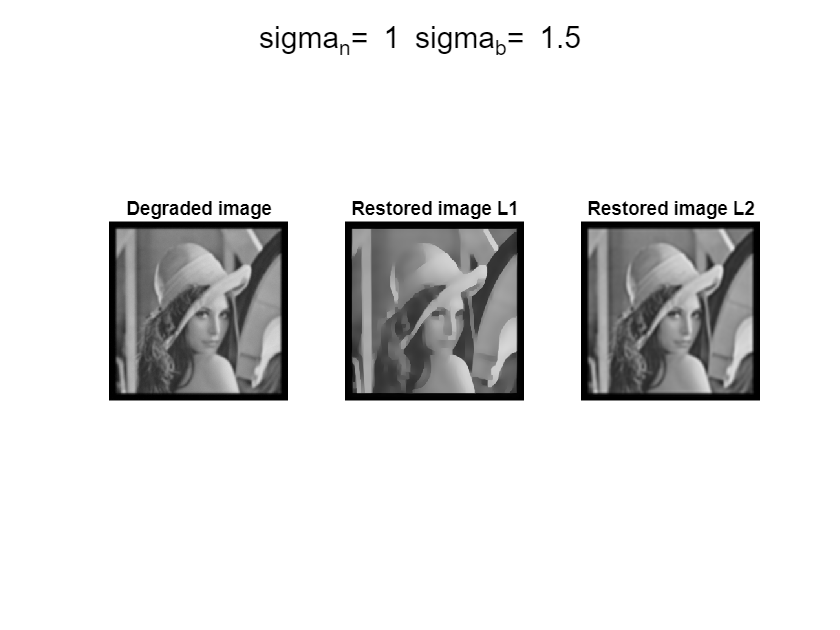


figure;
subplot(1,3,1);
imshow(degraded_image)
title('Degraded image')
subplot(1,3,2);
imshow(restored_image_L1)
title('Restored image L1')
subplot(1,3,3)
imshow(restored_image_L2)
title('Restored image L2')
sgtitle(['sigma_n= ',num2str(sigma_n),' sigma_b= ', ...
    num2str(sigma_b)])

sigma_n = 5;
sigma_b = 1.5;
degraded_image = degrade(lena, sigma_b, sigma_n, false);
[best_lambda_L1, RMSE_L1] = best_lambda(lena, qx, qy, ...
    sigma_b, sigma_n, l_start, l_end, l_step, false, "L1");
[best_lambda_L2, RMSE_L2] = best_lambda(lena, qx, qy, ...
    sigma_b, sigma_n, l_start, l_end, l_step, false, "L2");
restored_image_L1 = deblur_L1(degraded_image, sigma_b, best_lambda_L1, ...
    false);
restored_image_L2 = deblur_L2_freq(degraded_image, sigma_b, ...
    best_lambda_L2, qx, qy, false);
display(['Best lambda values for sigma_n = ', num2str(sigma_n),' and sigma_b = ', ...
    num2str(sigma_b),' for L1 = ', num2str(best_lambda_L1), ' and for L2 =', ...
    num2str(best_lambda_L2)])

Best lambda values for sigma_n = 5 and sigma_b = 1.5 for L1 = 0.07 and for L2 =0.51


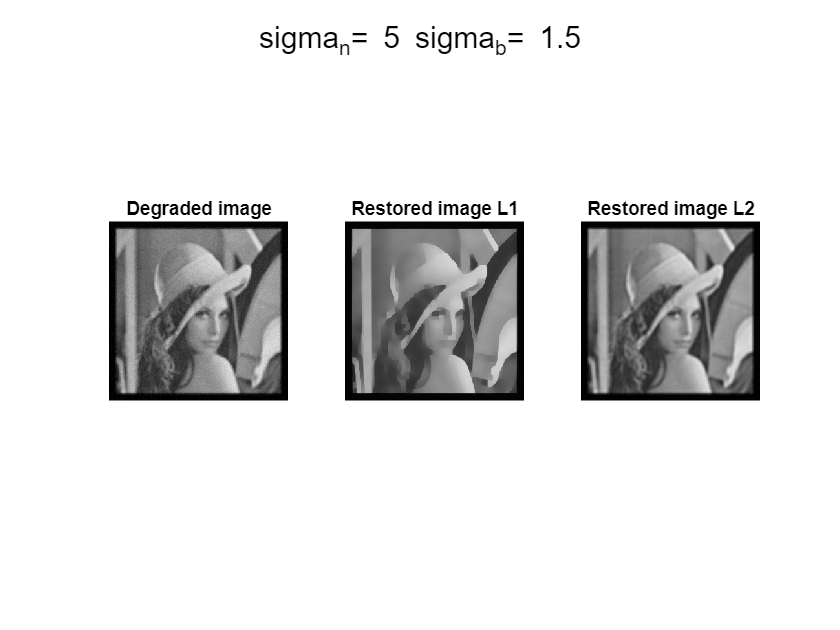


figure;
subplot(1,3,1);
imshow(degraded_image)
title('Degraded image')
subplot(1,3,2);
imshow(restored_image_L1)
title('Restored image L1')
subplot(1,3,3)
imshow(restored_image_L2)
title('Restored image L2')
sgtitle(['sigma_n= ',num2str(sigma_n),' sigma_b= ', ...
    num2str(sigma_b)])


sigma_n = 5;
sigma_b = motion_blur_kernel;
degraded_image = degrade(lena, sigma_b, sigma_n, true);
[best_lambda_L1, RMSE_L1] = best_lambda(lena, qx, qy, ...
    sigma_b, sigma_n, l_start, l_end, l_step, true, "L1");
[best_lambda_L2, RMSE_L2] = best_lambda(lena, qx, qy, ...
    sigma_b, sigma_n, l_start, l_end, l_step, true, "L2");
restored_image_L1 = deblur_L1(degraded_image, sigma_b, best_lambda_L1, ...
    true);
restored_image_L2 = deblur_L2_freq(degraded_image, sigma_b, ...
    best_lambda_L2, qx, qy, true);
display(['Best lambda values for sigma_n = ', num2str(sigma_n),' and sigma_b = motion blur kernel ', ...
        ' for L1 = ', num2str(best_lambda_L1), ' and for L2 =', ...
    num2str(best_lambda_L2)])

Best lambda values for sigma_n = 5 and sigma_b = motion blur kernel  for L1 = 0.11 and for L2 =1.18


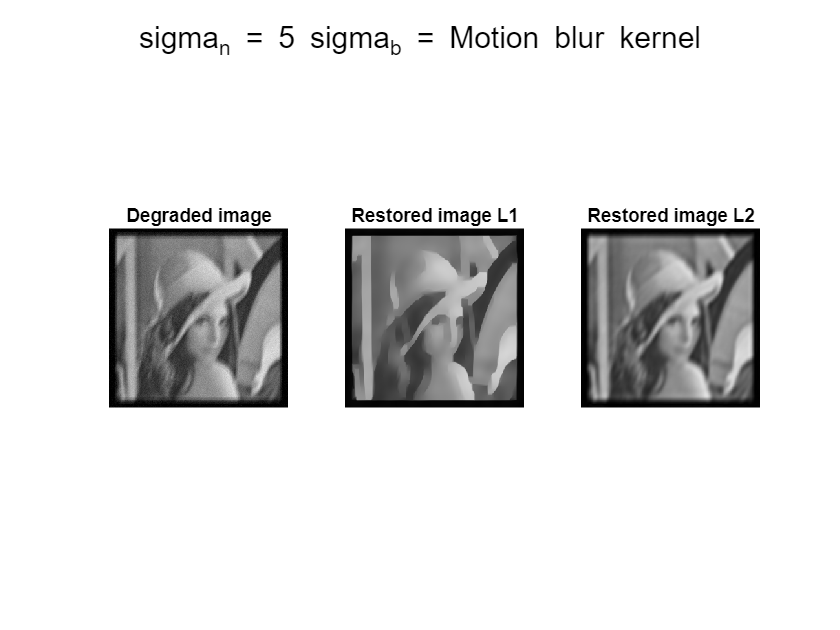

figure;
subplot(1,3,1);
imshow(degraded_image)
title('Degraded image')
subplot(1,3,2);
imshow(restored_image_L1)
title('Restored image L1')
subplot(1,3,3)
imshow(restored_image_L2)
title('Restored image L2')
sgtitle(['sigma_n = ',num2str(sigma_n),' sigma_b = Motion blur kernel']);

## Related Functions

### Lambda and Minimum RMSE

The following functions are used to get the best lambda based on the minimum RMSE for L1 and L2.

- Get Gaussian kernel given a sigma value

function kernel = gaussian_kernel(sigma)
        kernel_size = ceil(6*sigma);
        if mod(kernel_size, 2) == 0
                kernel_size = kernel_size+1;
        end
        d = ceil(kernel_size/2);
        if d == 0
                kernel = ones(kernel_size,kernel_size);
        else
                [x, y] = meshgrid(1:kernel_size, 1:kernel_size);
                exponent = -((x-d).^2 + (y-d).^2)/(2*sigma^2);
                kernel = exp(exponent);
                kernel = kernel/sum(kernel(:));
        end
end

        2. Add Gaussian Noise given sigma

function noisy_image = gaussian_noise(image, sigma)
        noisy_image = imnoise(image, 'gaussian', 0,  sigma^2);
end

        3. Degrades the image

function degraded_image = degrade(image, blur_param, sigma_n, is_motion_blur)
        rng(1);
        image = im2double(image);
%         convert noise std in the appropriate range
        sigma_n = sigma_n/255;
        if ~is_motion_blur
                blur_kernel = gaussian_kernel(blur_param);
                blurred_image = conv2(image, blur_kernel, 'same');
%                 add noise
                degraded_image = gaussian_noise(blurred_image, sigma_n);
        else
                blurred_image = conv2(image, blur_param, 'same');
%                 add noise
                degraded_image = gaussian_noise(blurred_image, sigma_n);
        end
end

        4. Now get the RMSE values for varying lambda values

function [lambda_best, rmse_vals] = best_lambda(image, qx, qy, ...
    blur_param, sigma_n,start_lambda, stop_lambda, step_size, is_motion_blur, reg)
        [x, y] = size(image);
        if ~is_motion_blur
                h = gaussian_kernel(blur_param);
                H = psf2otf(h, [x y]);
        else
                h = blur_param;
                H = psf2otf(blur_param, [x y]);
        end
        Qx = psf2otf(qx, [x y]);
        Qy = psf2otf(qy, [x y]);
        degraded_image = degrade(image, blur_param, sigma_n, is_motion_blur);
        lambda_vals = start_lambda:step_size:stop_lambda;
        n_lambda_vals = length(lambda_vals);
        rmse_vals = zeros(size(lambda_vals));
        lambda_best = start_lambda;
        rmse_best = Inf;
        if reg == "L1"
                for i = 1:n_lambda_vals
                        lambda = lambda_vals(i);
                        clean_image = admmfft(degraded_image, h, lambda, 1);
                        rmse = immse(clean_image, degraded_image);
                        rmse_vals(i) = rmse;
                        if rmse < rmse_best
                                rmse_best = rmse;
                                lambda_best = lambda;
                        end
                end
        elseif reg == "L2"
                for i = 1:n_lambda_vals
                        lambda = lambda_vals(i);
                        G = fft2(degraded_image);
                        freq_trans = conj(H)./(abs(H).^2+lambda*(abs(Qx).^2)+lambda*(abs(Qy).^2));
                        clean_image = abs(ifft2(freq_trans.*G));
                        rmse = immse(clean_image, degraded_image);
                        rmse_vals(i) = rmse;
                        if rmse < rmse_best
                                rmse_best = rmse;
                                lambda_best = lambda;
                        end
                end
        end
end

### Image deblurring

The following functions perform image deblurring based on L1/L2 norm

function clean_img = deblur_L2_freq(g, blur_param, lambda, qx, qy, is_motion_blur)
        [x, y] = size(g);
        if ~ is_motion_blur
                h = gaussian_kernel(blur_param);
                H = psf2otf(h, [x y]);
        else
                H = psf2otf(blur_param, [x y]);
        end
%         get the matrices as defined in the assignment PDF
        Qx = psf2otf(qx, [x y]);
        Qy = psf2otf(qy, [x y]);
%         calculate the 2D DFT
        G = fft2(g);
%         Formula as derived
        freq_trans = conj(H)./(abs(H).^2+lambda*(abs(Qx).^2)+lambda*(abs(Qy).^2));
%         Calculate the 2D IDFT
        clean_img = abs(ifft2(freq_trans.*G));
end

function clean_image = deblur_L1(g, blur_param, lambda, is_motion_blur)
        if ~ is_motion_blur
                h = gaussian_kernel(blur_param);
                clean_image = admmfft(g, h, lambda, 1);
        else
                clean_image = admmfft(g, blur_param, lambda, 1);
        end
end